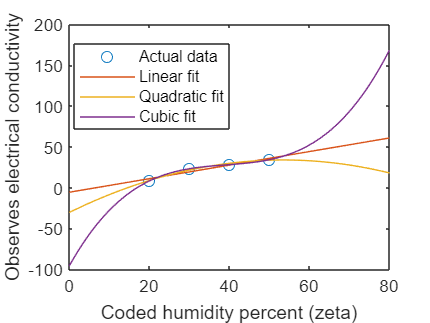

zeta = [20 30 40 50];
conductivity = [8 23 28 34];

coded = (zeta - 35) / 5;

linear = polyfit(zeta, conductivity, 1);
quadratic = polyfit(zeta, conductivity, 2);
cubic = polyfit(zeta, conductivity, 3);

x = linspace(0, 80);
y_linear = polyval(linear, x);
y_quadratic = polyval(quadratic, x);
y_cubic = polyval(cubic, x);

figure;
plot(zeta, conductivity, 'o');
hold on;
plot(x, y_linear);
plot(x, y_quadratic);
plot(x, y_cubic);
xlabel("Coded humidity percent (zeta)");
ylabel("Observes electrical conductivity");
legend("Actual data", "Linear fit", "Quadratic fit", "Cubic fit", location="best");
hold off;


%{
Interpolation would most reliably be conducted using the cubic fit
Extrapolation would most reliably be conducted using the linear fit
%}